# HIL Testing of a More Electric Aircraft Energy Management System

## Description

This reference application demonstrates how to perform model-in-the-loop (MIL) and hardware-in-the-loop (HIL) testing of an energy magement system (EMS) design for a More Electric Aircraft (MEA). The MEA plant model used in this example is based on MathWorks' Energy Management Systems for a Hybrid Electric Source example [1]. The plant model represents a fuel cell hybrid power system that is based on the emergency flight profile of a Bombardier aircraft. The system comprises the following components:

- A 12.5 kW (peak), 30-60 V proton exchange membrane (PEM) fuel cell power module (FCPM), with nominal power of 10 kW.

- A 48 V, 40 Ah, Li-ion battery system.

- A 291.6 V, 15.6 F, supercapacitor system (six 48.6v cells in series)

- A 12.5 kW fuel cell DC/DC boost converter, with regulated output voltage and input current limitation.

- Two DC/DC converters for discharging (4 kW boost converter) and charging (1.2 kW buck converter) the battery system. 

- A 15 kVA, 270 V DC in, 200 V AC, 400 Hz inverter system.

- A 3 phase AC load with variable apparent power and power factor, to emulate the MEA emergency load profile.

- A 15 kW protecting resistor to avoid overcharging the supercapacitor and battery systems.

In addition to the MEA emergency power system, the example includes EMS controls, which distribute power among the energy sources. EMS strategy is based on a classical PI control approach.

### **Learn how to:**

- Model and simulate an emergency power system of a More Electric Aircraft (MEA) composed of fuel cells, lithium-ion batteries and supercapacitors

- Seamlessly transition from MIL to HIL within Simulink without changing your model 

- Interface the MEA digital twin with the EMS controller using ARINC 429

- Leverage HIL simulation to validate EMS controls in emergency landing scenarios

## **Supported Model-based Design Use Cases **

This example supports the following simulation modes (see image below):

- Desktop MIL: Both the MEA plant and EMS controller run on the development computer. Use this simulation mode to test and verify the EMS controls and MEA emergency power system in closed-loop desktop simulation.

- Real-time MIL: Both the MEA plant and EMS controller run in real-time on a Speedgoat HIL test system to validate real-time aspects. The development computer is used to control the simulation, fine-tune plant and controller parameters, and measure and record real-time data.

- Real-time MIL with ARINC loopback: Both the MEA plant and EMS controller run in real-time on a Speedgoat HIL test system to validate real-time aspects. Extend the MEA plant with ARINC 429 bus. Validate EMS controls and bus communication in real-time.

- HIL: Interface a real EMS controller hardware with the MEA digital twin running on Speedgoat harwdare to perfrom interactive and automated HIL testing.

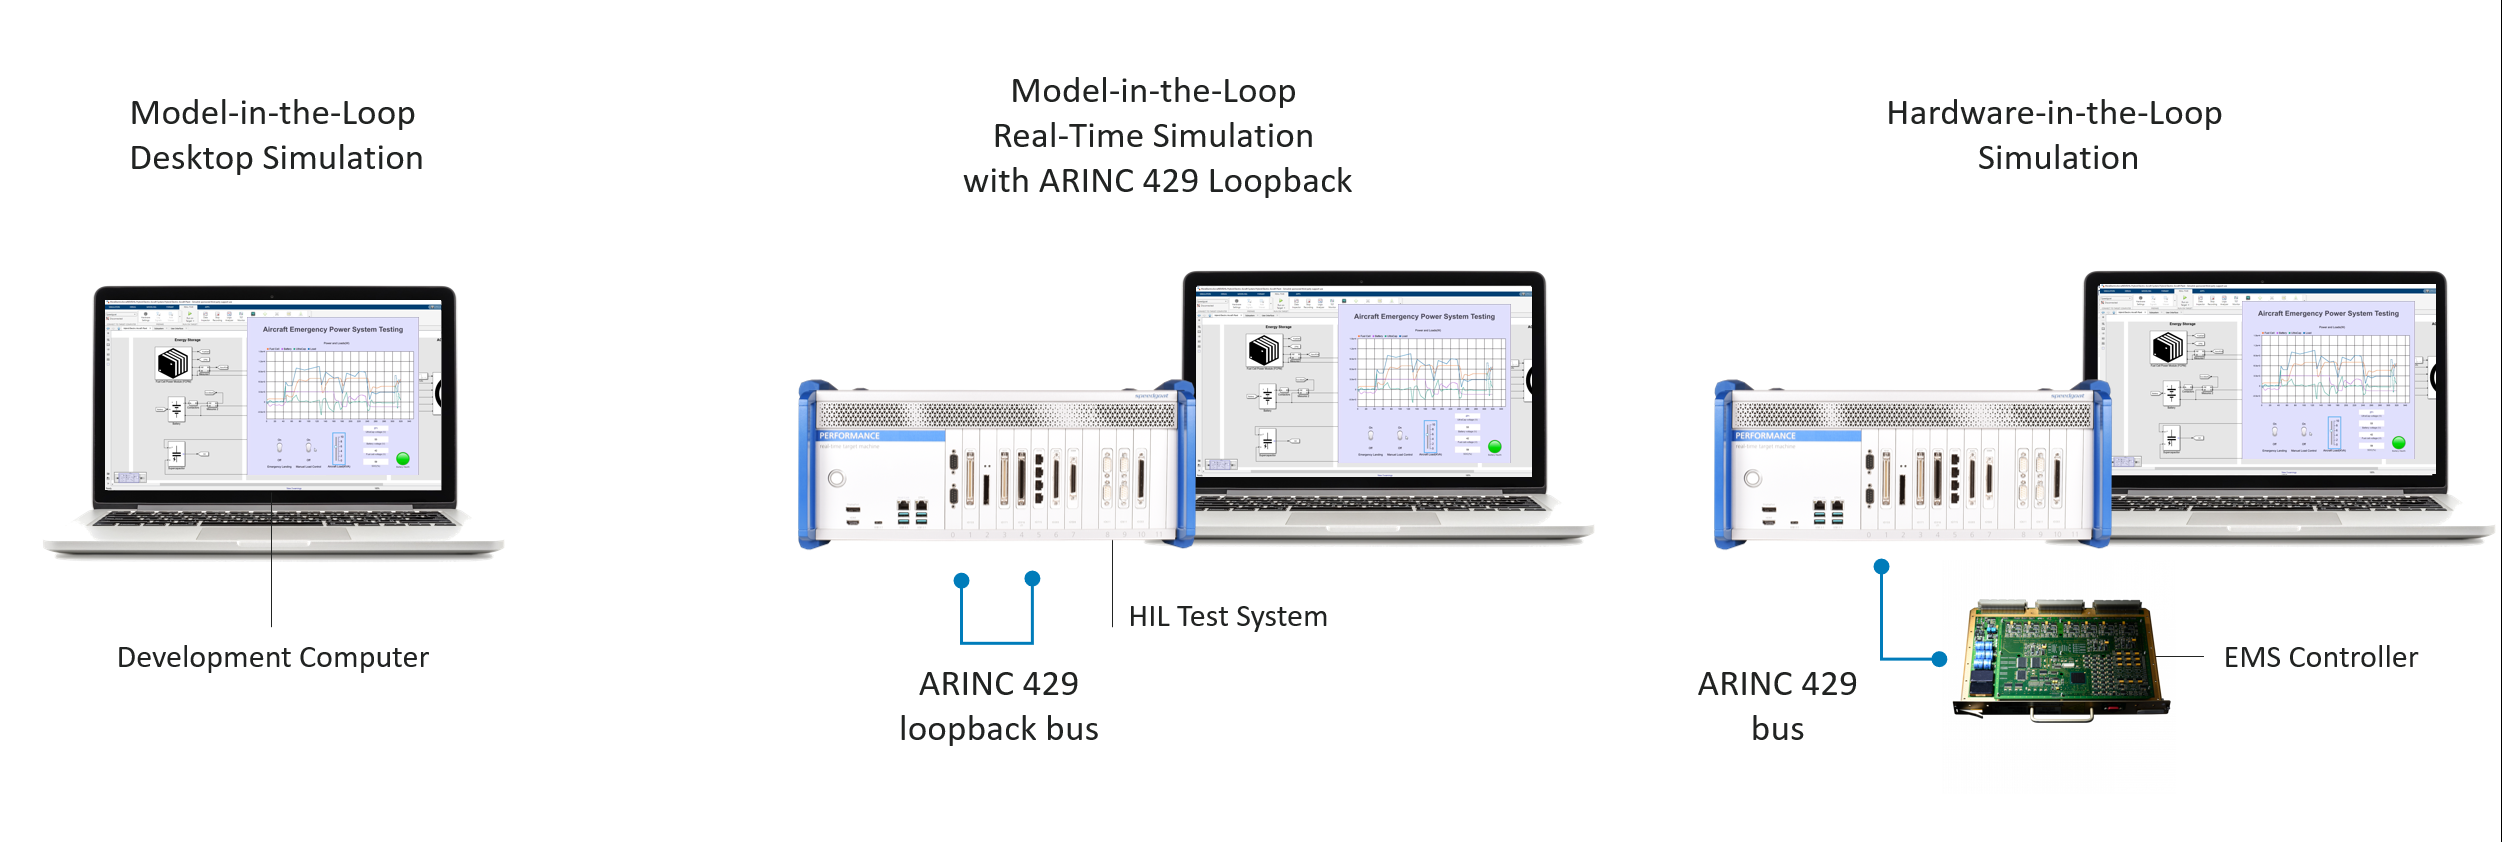

## System Requirements

###     MathWorks Products

-  [Simulink Real-Time™](https://www.mathworks.com/products/simulink-real-time.html)

-  [Simscape Electrical™](https://www.mathworks.com/products/simscape-electrical.html)

###     Speedgoat products

-   [Performance Real-Time Target Machine](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)

-   [IO682: Intelligent ARINC 429 I/O Module](https://www.speedgoat.com/products/communication-protocols-arinc-afdx-io682)

## Testbench Configuration 

### **    Configure testbench for MIL simulation**

mdl = 'MoreElectricAircraftEMSHIL';
open_system(mdl);
switchConfig(mdl,'MIL'); 

### **    Configure testbench for MIL with ARINC 429 loopback simulation**

mdl = 'MoreElectricAircraftEMSHIL';
open_system(mdl);
switchConfig(mdl,'LBK'); 

### **    Configure testbench for HIL simulation**

mdl = 'MoreElectricAircraftEMSHIL';
open_system(mdl);
switchConfig(mdl,'HIL'); 

    Note: For Hardware-in-the-Loop testing, user need to set up the ARINC 429 I/O interface on the controller side accordingly (use the loopback example as reference)

## **Exercise -  EMS Testing for a F**ive-Minute Emergency Landing Scenario

### **    Run MIL simulation**

% Start dekstop simulation
set_param(mdl, 'SimulationCommand', 'start')

### **    Run MIL with ARINC 429 loopback or HIL simulation**


% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Build the Simulink model
slbuild(mdl);   
  
% Download and install the real-time application on the target machine
tg.load(mdl);
  
% Start simulation of real-time application
tg.start;

The demonstration consists of an interactive testing of the EMS controller and fuel cell hybrid emergency power system during a five minutes emergency landing scenario. In this scenario, the fuel cell hybrid power system supplies the essential loads during the following events:

- Instantly when the main generators are lost (this is normally assumed by the Avionic and APU battery system till the RAT/ADG is fully deployed).

- Emergency hydraulic pump start-ups.

- Motion of Flaps/Slats and gear down.

- Taxiing and passengers evacuation (also normally assumed by the Avionic and APU battery system as the RAT/ADG becomes unavailable).

**Key things to observe: **

- Fuel-cell is the main power source but it’s slow (e.g. roughly around 40-70sec, 125-140sec, 170-200sec, 235-250sec).  

- For the fast transient, supercapacitor can react very quickly (e.g. around 40sec, 130sec, 180sec, 235sec) but it could make the bus voltage fluctuate (270 Volt as reference in this case).  

- Battery will react to the voltage fluctuation (e.g. around 45sec, 175 and 190sec, 240sec) and also as a secondary power source when the load is higher than the fuel-cell capacity (e.g. roughly around 75-125sec).  

- Battery can also absorb the power as the energy storage (e.g. before 40sec and after 330sec).  

- When both fuel-cell and battery reached to their maximum capacities, the supercapacitor can also make up the remaining power (e.g. 110 to 125sec)

**Some key maneuvers during this emergency landing simulation:**

- Before t = 40 s, preparing for unlikely emergency landing.  Zero load to the hybrid power system.  Fuel-cell operates at optimal power around 1KW and charges the battery

         Sudden load changes: 

- At t = 40 s, all generators lost. The fuel cell hybrid power system takes over the essential loads. At this time the extra load power required is instantly supplied by the supercapacitor due to its fast dynamics, while the fuel cell power increases slowly.

- At t= 45 s, the supercapacitor is discharged below the required DC bus voltage (270 V) and the battery starts providing power to regulate the bus voltage back to 270 V.

- At t = 60 s, an emergency hydraulic pump is started, and the supercapacitor provides the extra transient load power, while the fuel cell power increases slowly.

- At t = 130 s, the second emergency hydraulic pump is started.

- At t = 180 s, the load is suddenly increased due to the motion of Flaps/Slats and landing gears. Once again, the supercapacitor responds quickly by providing the extra load power.

- At t = 235 s, the aircraft has landed and the load power decreases suddenly. The extra fuel cell energy is stored in the battery and supercapacitor.

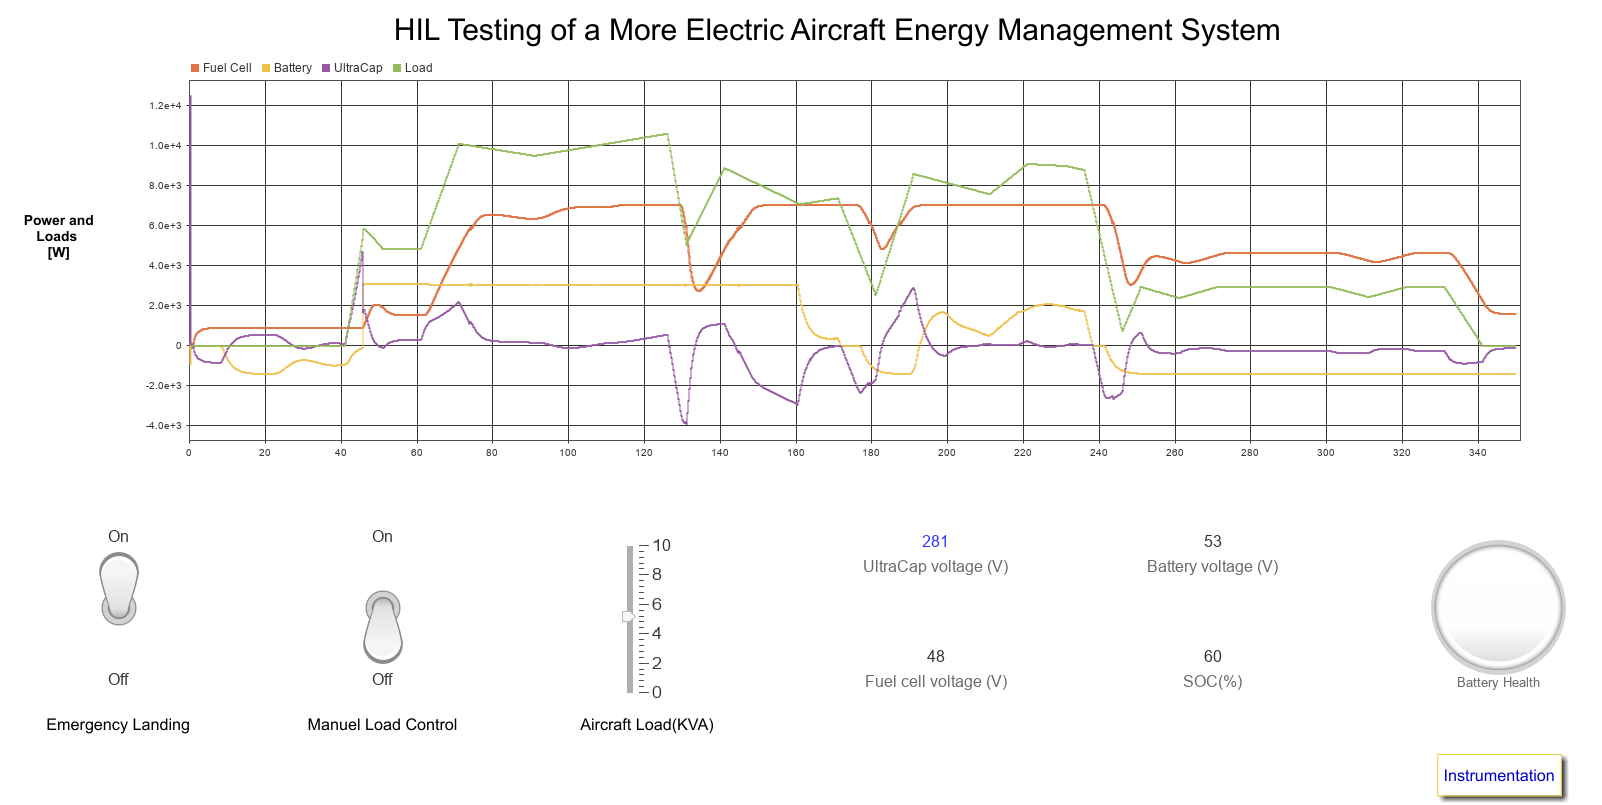

User can override the pre-defined load profile and perfrom interactive testing using the various user interface components. To do that, swicth the ‘Manual Load Control’ ON and tune the ‘Aircraft Load (KVA)’ value.   

## Related Content

- [Real-Time Testing for VTOL and Conventional Aircraft Development](https://www.speedgoat.com/knowledge-center/webinars/real-time-testing-for-vtol-and-conventional-aircraft-development)

- [Electric Aircraft Modeling and Simulation](https://www.mathworks.com/videos/electric-aircraft-modeling-and-simulation-1596098562837.html)

- [More Electric Aircraft](https://www.speedgoat.com/solutions/industries/aerospace/more-electric-aircraft)

- [Aerospace Protocols](https://www.speedgoat.com/products-services/i-o-connectivity/protocols/aerospace)

## References

[1] [Energy Management Systems for a Hybrid Electric Source (Application for a More Electric Aircraft)](https://www.mathworks.com/help/releases/R2023a/sps/ug/energy-management-systems-for-a-hybrid-electric-source-application-for-a-more-electric-aircraft.html?s_tid=doc_srchtitle)

## Release Notes

open README.md